# Rock No Rock: IMU analysis

Enter subject code 

subName = 'eg';

Run subject's data LiveScript to get data table

T = 1×6 table
    number     code      sex     age    mass     h  
    ______    ______    _____    ___    ____    ____

      5       {'eg'}    {'M'}    30     148     1.78


listHang =     7.4000
   14.8000
   26.6400


Predicted maximal power output = 814.5 Watts 
Predicted optimal cadence = 102.0 rpm 
Predicted optimal hanging mass =  8.4 kg (18.5 lb) 


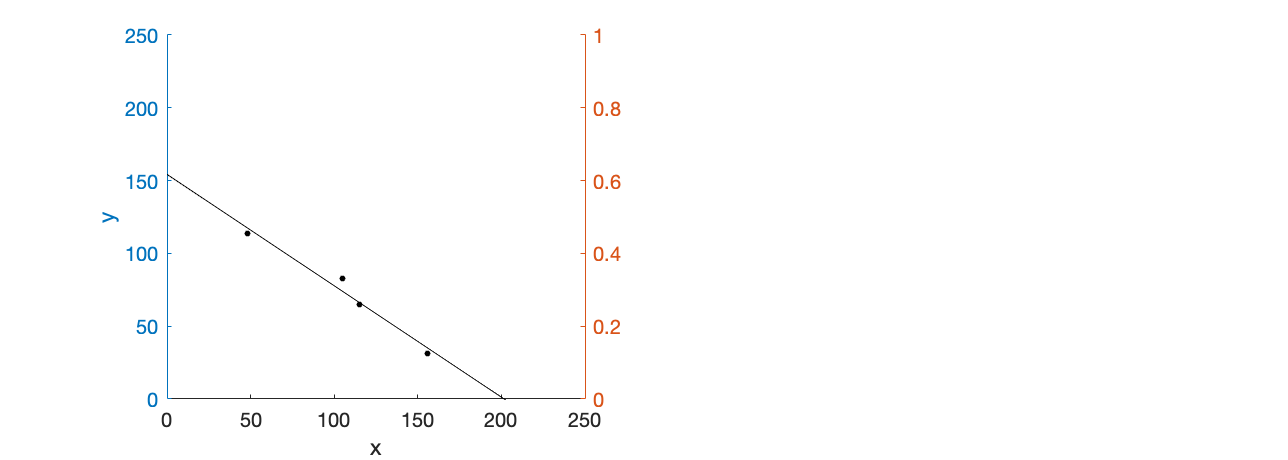

Estimated coefficient of friction on flywheel =  1.1 


f = struct with fields:
           c1: [1×1 cfit]
          gof: [1×1 struct]
     maxPower: 814.4802
       optCad: 102
      optHang: 8.3760
    maxTorque: 154.2758
         data: [4×5 table]


ans =      2     3     1


ans =      2     3     1


ans =      2     3     1


T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       5           1          1          17.5          908       105  
       5           2          1          17.5          787        96  
       5           3          1          17.5          808       100  
       5           3          2          17.5          829       103  
       5           1          2          17.5          859       104  
       5           2          2          17.5          683        92  
       5           2          3          17.5          774        99  
       5           3          3          17.5          821       103  
       5           1          3          17.5          899       106  

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           888.67            105   
        2            3              748         95.667   
        3            3           819.33            102   


ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3          26.083             1   
        2            3          56.666        3.5119   
        3            3          10.599        1.7321   


ans = 3×3 table
    condition    GroupCount    Fun_lean
    _________    __________    ________

        1            3          11.692 
        2            3          2.3604 
        3            3          1.0629 


ans = 3×3 table
    condition    GroupCount    Fun_lean
    _________    __________    ________

        1            3          2.2146 
        2            3         0.69288 
        3            3         0.17633 


run(['data_' subName '.mlx']);

clc;close all
clearvars -except T T_ subName

Enter trial name

condition = 2;
trial = 2;
trialName = ['0',num2str(condition),'0',num2str(trial)];

Load Garmin data file into table

filePath = '/Users/rosswilkinson/Google Drive/projects/rock-no-rock/data/';
fileName = [subName '_' trialName '_power'];
tP = readtable([filePath fileName]);

Load IMU data file for crank

filePath = '/Users/rosswilkinson/Google Drive/projects/rock-no-rock/data/';
fileName = [subName '_' trialName '_crank'];
tC = readtable([filePath fileName]);

Load IMU data file for frame

filePath = '/Users/rosswilkinson/Google Drive/projects/rock-no-rock/data/';
fileName = [subName '_' trialName '_frame'];
tF = readtable([filePath fileName]);

Sync Garmin and IMU data

- convert imu accelerations into resultant acceleration

x = tC.accel_x_m_s2_; % vertical axis
y = tC.accel_y_m_s2_;
z = tC.accel_z_m_s2_;
tC.accel_res = sqrt(x.^2 + y.^2 + z.^2);
x = tF.accel_x_m_s2_; % vertical axis
y = tF.accel_y_m_s2_;
z = tF.accel_z_m_s2_;
tF.accel_res = sqrt(x.^2 + y.^2 + z.^2);

Find sync spike in crank and frame IMU

[~,syncC] = findpeaks(tC.accel_res,'minPeakHeight',50,"NPeaks",1);
[~,syncF] = findpeaks(tF.accel_res,'minPeakHeight',50,"NPeaks",1);

Crop signals to sync spike

tC_ = tC(syncC:end,:);
tF_ = tF(syncF:end,:);
tC_.timestamp = tC_.timestamp - tC_.timestamp(1);
tF_.timestamp = tF_.timestamp - tF_.timestamp(1);

Lowpass filter acceleration signal of x axis (vertical axis)

freq = 500;
pass = 2;
tC_.accel_x_m_s2_ = lowpass(tC_.accel_x_m_s2_,pass,freq);
tF_.accel_y_m_s2_ = lowpass(tF_.accel_y_m_s2_,pass,freq);

Interpolate power data to match IMU sampling frequency

x = 0:height(tP)-1;
v = table2array(tP);
xq = 0:1/500:height(tP)-1;
temp = interp1(x',v,xq',"linear");
tP_ = array2table(temp,"VariableNames",tP.Properties.VariableNames);

Crop all signals to when power is being produced

k = tP_.watts > 0;
t1 = min(tP_.secs(k));
t2 = max(tP_.secs(k));

tP_ = tP_(k,:);
tC_ = tC_(tC_.timestamp > t1 & tC_.timestamp < t2,:);
tF_ = tF_(tF_.timestamp > t1 & tF_.timestamp < t2,:);

Differentiate acceleration in y-axis to arc displacement

dt = 1/500;
acc = tF_.accel_y_m_s2_;
vel = diff(acc)*dt;
pos = interp1(1:length(vel)-1,diff(vel)*dt,1:length(acc));

Convert frame acceleration signals to angle

r = 0.53; % height of IMU above pivot in meters
tF_.theta = rad2deg(pos ./ r)';

Find peaks in crank signal

[~,locs] = findpeaks(tC_.accel_x_m_s2_,"MinPeakProminence",5,"MinPeakDistance",150);

Calculate range of bicycle lean during each crank cycle

for i = 1:numel(locs)-1
    leanRange(i) = range(tF_.theta(locs(i):locs(i+1)));
end
leanRange

leanRange = 	1.0e+-4 *

    0.3972    0.3691    0.3330    0.3016


T_.leanAngle(k) = max(leanRange);

Store peak lean angle in subject data table

k = T_.condition == condition & T_.trial == trial;

Plot power, frame angle, and crank accel.

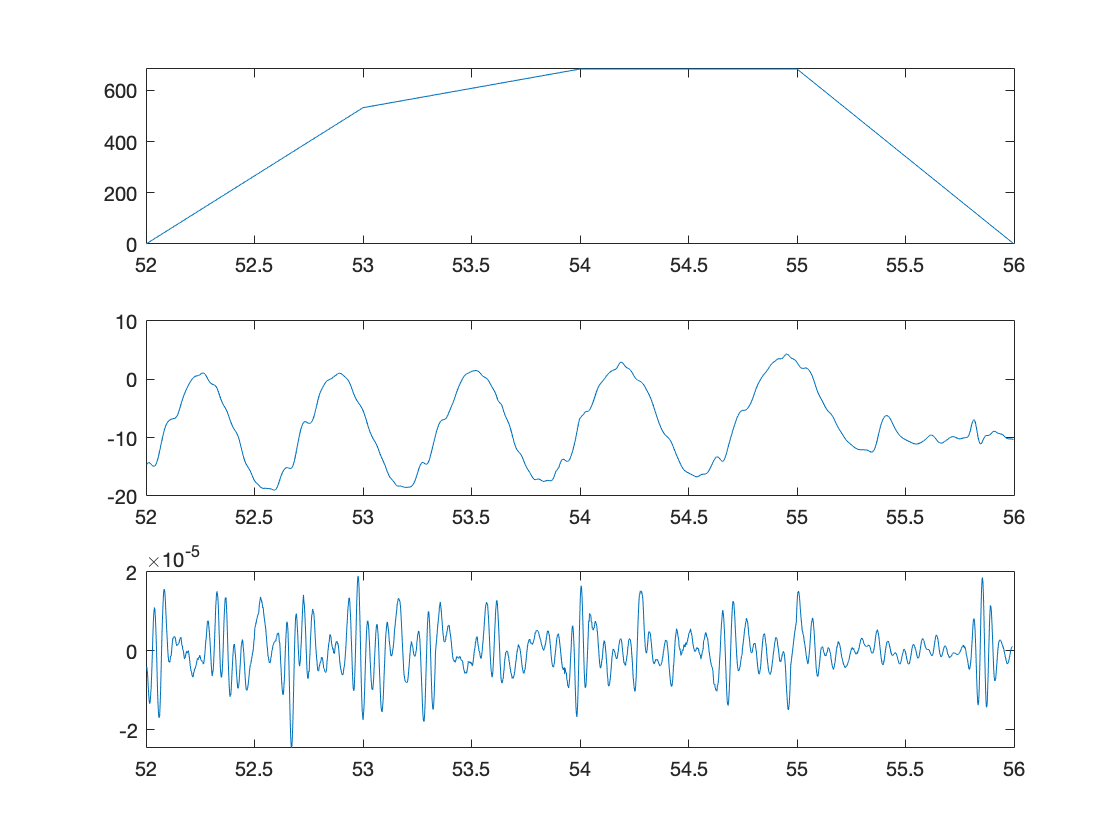

subplot(311)
plot(tP_.secs,tP_.watts)
subplot(312)
plot(tC_.timestamp,tC_.accel_x_m_s2_)
subplot(313)
plot(tF_.timestamp,tF_.theta)